# ODE solutions using numerical integration

We will solve the ODE we derived last class using a number of popular techniques and compare their efficiencies.

The governing ODE for frictional sliding of a spring-slider with linear velocity-dependant frictional strength, $\tau_f = f\sigma_n$ where $f = Av$, is


$$\frac{\mathrm{dv}}{\mathrm{dt}}=\frac{\;1}{A\sigma_n }\left({\sigma^˙ }^{\infty \;} -\mathrm{kv}\right)$$


We make a simplification here by saying that the loading rate $\dot{\sigma}^{\infty} = kv_{pl}$, where $v_{pl}$ is the long-term or the time-averaged sliding rate of the block.


$$\frac{\textrm{dv}}{\textrm{dt}}=\frac{\;k}{A\sigma_n }\left(v_{\mathrm{pl}} -\textrm{v}\right)$$


The analytical solution for this can be found through separation of variables and is coded as follows,

clear

% input parameters for ODE
Vpl = 1;
k = 3;
tauinf = k*Vpl;
Asigma = 0.5;

% relaxation time of the system
tr = Asigma/k;

% define ODE
dydt = @(t,v) (tauinf - k*v)/(Asigma);

% Analytical solution
ytrue = @(t,vi) vi*exp(-t./tr) + Vpl*(1-exp(-t./tr));


To solve this system uniquely, we need an initial condition, $v(t=0)$

% initial condition
vi = 30;

To solve the problem we define the timesteps where we want the solution

% solve using numerical methods

nsteps = 10;
t = linspace(0,10*tr,nsteps)';
dt = [0;diff(t)];

## Euler's explicit method

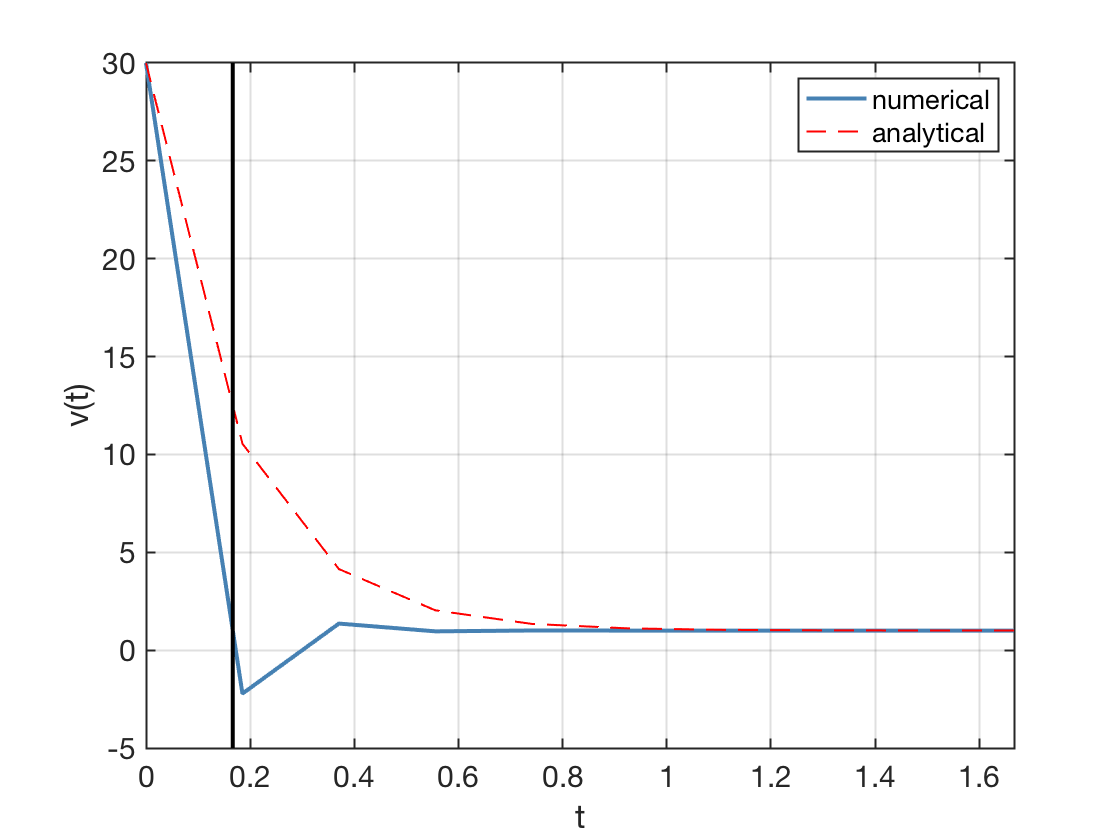

yeuler = zeros(nsteps,1);

yeuler(1) = vi;

for j=2:nsteps
    
    h = dt(j);
    
    yeuler(j,1) = yeuler(j-1,1) + h*dydt(t(j-1,1),yeuler(j-1,1));
    
end

figure(1),clf
plot(t,yeuler,'-','LineWidth',2,'Color',rgb('steelblue')), hold on
plot(t,ytrue(t,vi),'r--','LineWidth',1)
plot([1 1].*tr,get(gca,'YLim'),'k-','LineWidth',2)
axis tight, grid on
xlabel('t'),ylabel('v(t)')
legend('numerical','analytical')
set(gca,'FontSize',15,'YScale','lin','LineWidth',1)

## Heun's method

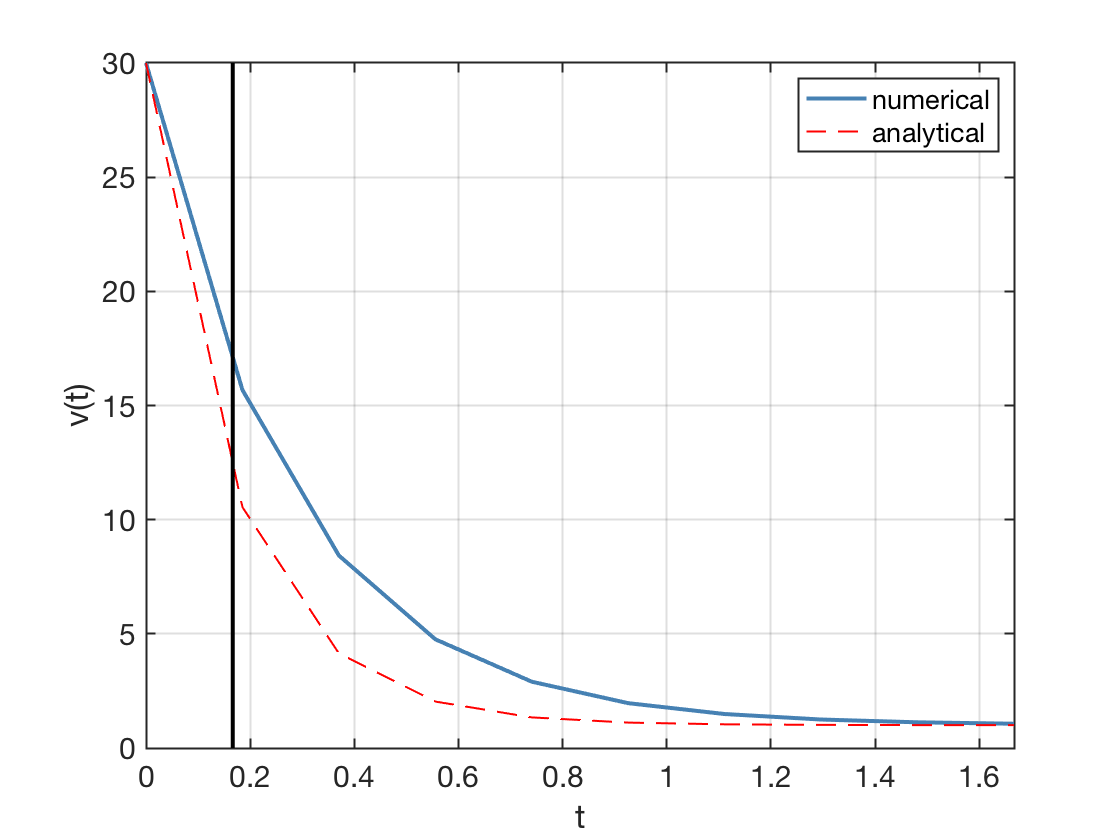

yheun = zeros(nsteps,1);
yheun(1) = vi;

for j=2:nsteps
    
    h = dt(j);
    
    k1 = h*dydt( t(j-1), yheun(j-1) );
    
    k2 = h*dydt( t(j-1)+h, yheun(j-1)+k1);
    
    yheun(j,1) = yheun(j-1) + 0.5*(k1+k2);
end

figure(1),clf
plot(t,yheun,'-','LineWidth',2,'Color',rgb('steelblue')), hold on
plot(t,ytrue(t,vi),'r--','LineWidth',1)
plot([1 1].*tr,get(gca,'YLim'),'k-','LineWidth',2)
axis tight, grid on
xlabel('t'),ylabel('v(t)')
legend('numerical','analytical')
set(gca,'FontSize',15,'YScale','lin','LineWidth',1)

## Runge-Kutta method

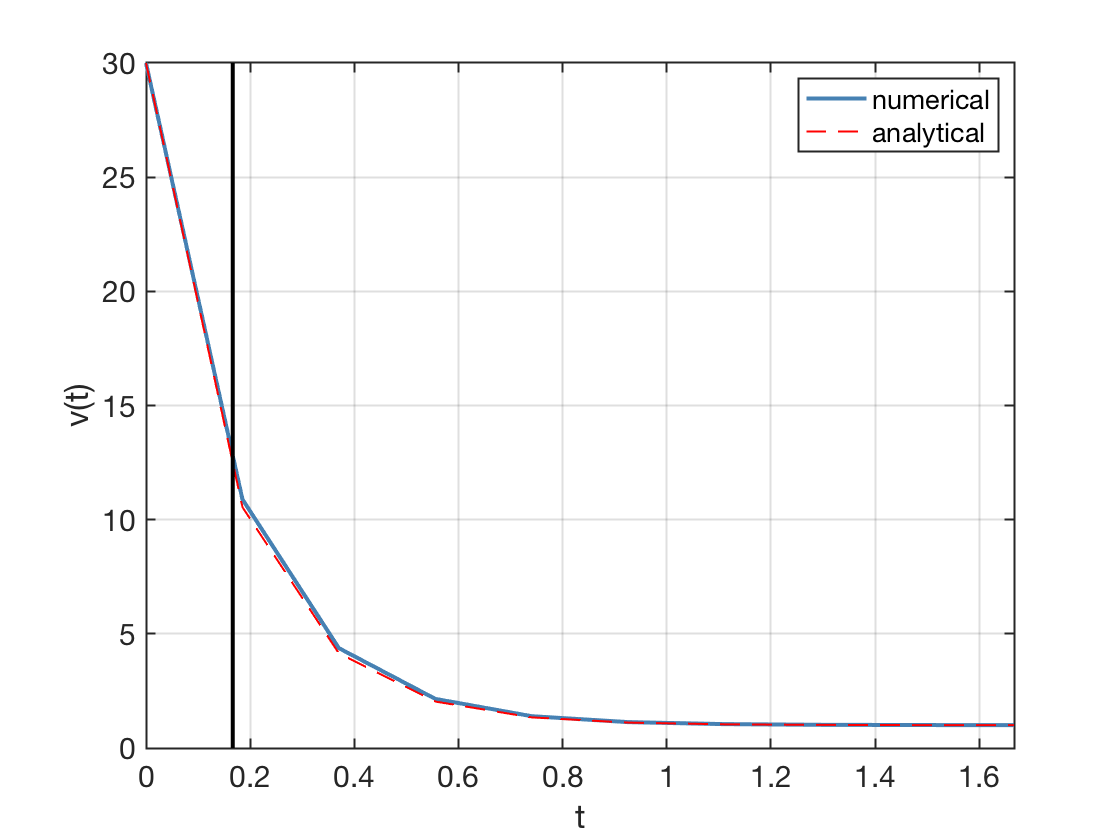

yrk = zeros(nsteps,1);
yrk(1) = vi;


for j=2:nsteps
    
    h = dt(j);
    
    k1 = h*dydt( t(j-1), yrk(j-1) );
    
    k2 = h*dydt( t(j-1)+h/2, yrk(j-1)+0.5*k1 );
    
    k3 = h*dydt( t(j-1)+h/2, yrk(j-1)+0.5*k2 );
    
    k4 = h*dydt( t(j-1)+h, yrk(j-1)+k3 );
    
    yrk(j,1) = yrk(j-1)+(1/6)*(k1+2*k2+2*k3+k4);
end

figure(1),clf
plot(t,yrk,'-','LineWidth',2,'Color',rgb('steelblue')), hold on
plot(t,ytrue(t,vi),'r--','LineWidth',1)
plot([1 1].*tr,get(gca,'YLim'),'k-','LineWidth',2)
axis tight, grid on
legend('numerical','analytical')
xlabel('t'),ylabel('v(t)')
set(gca,'FontSize',15,'YScale','lin','LineWidth',1)

## Compare all solutions

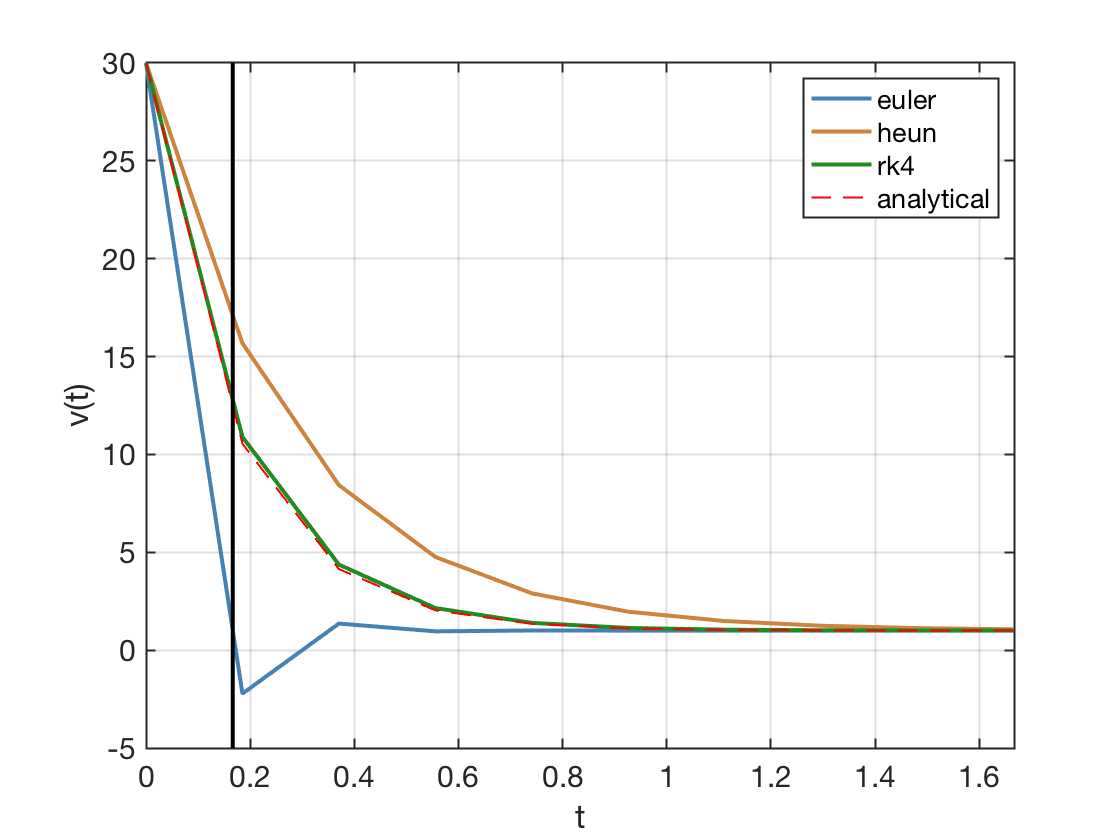

%%plot solutions

figure(1),clf
plot(t,yeuler,'-','LineWidth',2,'Color',rgb('steelblue')), hold on
plot(t,yheun,'-','LineWidth',2,'Color',rgb('peru'))
plot(t,yrk,'-','LineWidth',2,'Color',rgb('forestgreen'))

plot(t,ytrue(t,vi),'r--','LineWidth',1)
plot([1 1].*tr,get(gca,'YLim'),'k-','LineWidth',2)

axis tight, grid on
xlabel('t'),ylabel('v(t)')
legend('euler','heun','rk4','analytical')

set(gca,'FontSize',15,'YScale','lin','LineWidth',1)